# Diagnostics - USRP Sensing Subsystem

## Configure the configuration to test against

clear;
clf;
simulator = Simulator_revB();

config_folder_path = "./config_files/";
% config_name = "20MHz_USRP_revB.json";
config_name = "20MHz_USRP_500us.json";
simulator.load_params_from_JSON(config_folder_path + config_name);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters

simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 0.05 MHz/us
	 Idle Time: 			 1.92 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 7.68 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 0.52 MSps
	 Ramp End Time: 		 499.20 us
	 Chirp Tx Bandwidth: 		 25.00 MHz
	 Chirp Sampling Bandwidth: 	 24.62 MHz
	 ADC Sampling Period: 		 491.52 us
	 Chirp Cycle Time: 		 501.12 us
	 Chirp Wavelength: 		 199.86 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 400.40 ms
	 Active Frame Time 		 128.29 ms
Performance Specifications
	 Max Range 			 1558.92 m
	 Range Resolution 		 6.09 m
	 Max Velocity 			 99.71 m/s
	 Velocity Resolution 		 0.78 m/s
FMCW Specifications
	 FMCW sampling rate 		 25.00 MHz
	 Downsampling factor 		 48
	 Sweep time 			 499.20 us
	 Samples per chirp 		 12528.00 
CFAR Detection Region
	 Range Detection Region 		 24.358 m to 1528.476 m
	 Velocity Detection Region 		 -94.255 m/s to 95.034 m/s


### Save the victim chirp to a file

%save the full chirp as a binary file
path = "../MATLAB_generated/MATLAB_full_chirps/MATLAB_chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path,'float32');

### Plot Tx Chirp to confirm correctness

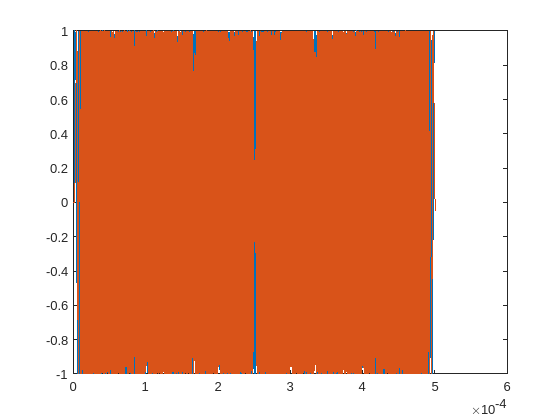

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

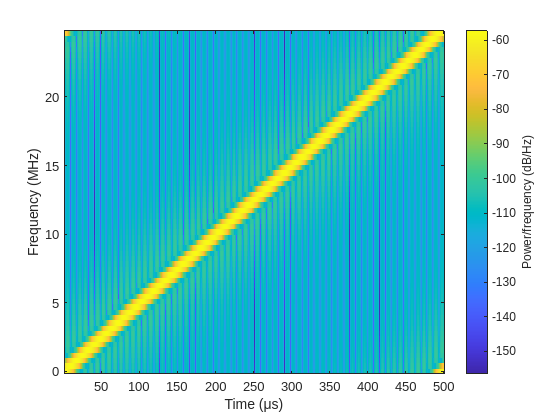

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## RUN EXPERIMENT ON USRP DEVICE - SESING ONLY (enable debug on sensing subsystem)

### Load key sensing subsystem parameters from USRP Implementation

### Spectrogram Generation

#### Get key initialization parameters

num_rows = 669;
fft_size = 256;
samples_per_sampling_window = 375;
samp_freq = 25.000 * 1e6;

%load the times/frequencies used for spectrogram generation in the cpp code
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_spectrogram_times.bin";
spectrogram_times = simulator.read_from_file(path,false,"double");

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_spectrogram_frequencies.bin";
spectrogram_frequencies = simulator.read_from_file(path,false,"double");

fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
    num_rows,samples_per_sampling_window,fft_size,samp_freq);

 rows: 669 
 samples per sampling window: 375 
 fft size: 256 
 samp freq: 25000000

#### Verify Hanning Window

%get the hanning window
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_hanning_window.bin";
read_data = simulator.read_from_file(path,true,"float");

%compare with the computed hanning window
compare = all(abs(read_data - hann(fft_size)) < 1e-5);
if compare
    fprintf("Hanning window matches")
else
    fprintf("Hanning window doesn't match")
end

Hanning window matches

#### Reshape Received Signal - read and verify

%get the reshaped for fft signal
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_reshaped_and_windowed_for_fft.bin";

read_data = simulator.read_from_file(path,true,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

#### Generated Spectrogram

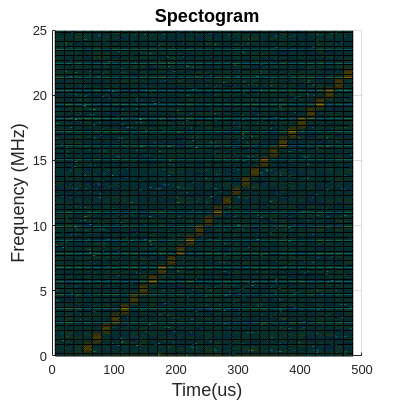

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_generated_spectrogram.bin";

read_data = simulator.read_from_file(path,false,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

max_time_to_plot_us = 500;
idx_to_plot = spectrogram_times < max_time_to_plot_us;

clf;
set(gcf,'Position',[100 100 400 400])
font_size = 14;
ax = gca;
ax.FontSize = font_size;
surf(spectrogram_times(idx_to_plot),...
    spectrogram_frequencies,...
    read_data_reshaped(:,idx_to_plot));
title_str = sprintf('Spectogram');
title(title_str,"FontSize",font_size);
xlabel('Time(us)',"FontSize",font_size)
ylabel('Frequency (MHz)',"FontSize",font_size)
view([0,90.0])

#### Detected Times and Frequencies - read and verify

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_detected_frequencies.bin";

read_data_detected_frequencies = simulator.read_from_file(path,false,"double");

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_detected_times.bin";
read_data_detected_times = simulator.read_from_file(path,false,"double");

#### Clusters - read and verify

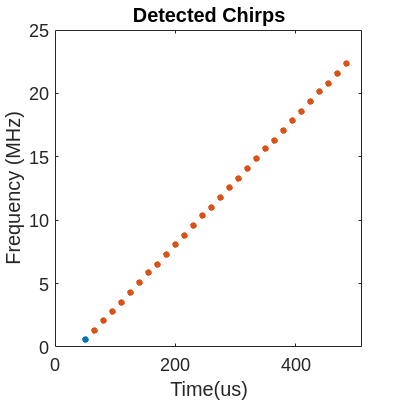

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_computed_clusters.bin";
read_data = simulator.read_from_file(path,false,"int");
read_data_idx = read_data(read_data ~= 0);

idx_to_plot = read_data_detected_times < max_time_to_plot_us;

clf;

gscatter(read_data_detected_times(idx_to_plot), ...
    read_data_detected_frequencies(idx_to_plot), ...
    read_data_idx(idx_to_plot));
set(gcf,'Position',[100 100 400 400])
font_size = 14;
title_str = sprintf('Detected Chirps');
title(title_str,"FontSize",font_size);
xlabel('Time(us)',"FontSize",font_size)
ylabel('Frequency (MHz)',"FontSize",font_size)
ax = gca;
ax.FontSize = font_size;
legend off;

#### Computed Linear Models

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_detected_slopes.bin";
read_data_detected_slopes = simulator.read_from_file(path,false,"double")

read_data_detected_slopes =     0.0501
    0.0501
    0.0501
    0.0501
    0.0501
    0.0501
    0.0501
    0.0501
    0.0501
    0.0501




path = "../MATLAB_generated/cpp_sensed_parameters/cpp_detected_intercepts.bin";
read_data_intercepts = simulator.read_from_file(path,false,"double")

read_data_intercepts = 1.0e+07 *

    2.0000
    2.0001
    2.0001
    2.0002
    2.0002
    2.0003
    2.0003
    2.0004
    2.0004
    2.0005


%captured chirps buffer
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_chirp_estimates.bin";
captured_chirps_buffer = simulator.read_from_file(path,false,"double");
%captured slopes buffer
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_slope_estimates.bin";
captured_slopes_buffer = simulator.read_from_file(path,false,"double");
%captured frames buffer
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_frame_estimates.bin";
captured_frames_buffer = simulator.read_from_file(path,false,"double");

#### Captured Frames Array

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_captured_frames.bin";
read_data = simulator.read_from_file(path,false,"double");
captured_frames = reshape(read_data,6,[]).'

captured_frames = 1.0e+07 *

         0         0         0         0    0.0500         0
         0         0         0         0    0.1000    0.1501
         0         0         0         0    0.1500    0.2001
         0         0         0         0    0.2000    0.2501
         0         0         0         0    0.2500    0.3001
         0         0         0         0    0.3000    0.3501
         0         0         0         0    0.3500    0.4001
         0         0         0         0    0.4000    0.4501
         0         0         0         0    0.4500    0.5001
         0         0         0         0    0.5000    0.5501


estimation_errors_ns = (captured_frames(2:end - 1,6) - captured_frames(3:end,5) ...
    - simulator.Victim.ChirpCycleTime_us) * 1e3

estimation_errors_ns =   124.7000
  171.9445
 -359.8861
  306.7836
  -77.3322
   15.5777
   12.9343
   10.9330
  -29.7873
   53.3698


average_error_ns = mean(estimation_errors_ns(3:end))

average_error_ns = -1.5469

error_stdev_ns_squared = sqrt(var(estimation_errors_ns(3:end)))

error_stdev_ns_squared = 83.0542

### Get the estimated parameters

path = "../MATLAB_generated/cpp_sensed_parameters/cpp_estimated_parameters.bin";
read_data = simulator.read_from_file(path,false,"double");
estimated_frame_duration_ms = read_data(1);
estimated_chirp_duration_us = read_data(2);
estimated_chirp_slope_MHz_us = read_data(3);

% %print out the relevant information
fprintf("Average Frame Duration: %3.7f ms",estimated_frame_duration_ms);

Average Frame Duration: 499.9992425 ms

fprintf("Average Chirp Duration: %3.3f us",estimated_chirp_duration_us);

Average Chirp Duration: 501.121 us

fprintf("Average Slope: %1.3f MHz/us",estimated_chirp_slope_MHz_us);

Average Slope: 0.050 MHz/us

### Estimation Errors

% %print out the relevant information
actual_frame_duration_ms = 500;
fprintf("Frame Duration Error: %3.5f ns",(estimated_frame_duration_ms - actual_frame_duration_ms) * 1e6);

Frame Duration Error: -757.50000 ns

fprintf("Chirp Duration Error: %3.5f ns",(estimated_chirp_duration_us - simulator.Victim.ChirpCycleTime_us) * 1e3);

Chirp Duration Error: 0.87785 ns

fprintf("Slope Error: %1.5f MHz/us",estimated_chirp_slope_MHz_us - simulator.Victim.FrequencySlope_MHz_us);

Slope Error: -0.00000 MHz/us

### Computed Victim Waveform from Attacker

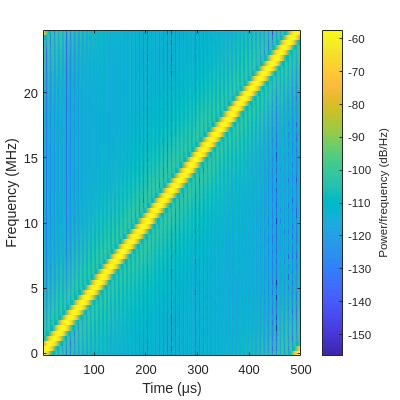

clf;
path = "../MATLAB_generated/cpp_sensed_parameters/cpp_computed_victim_waveform.bin";
estimated_waveform = simulator.read_from_file(path,true,"float32");
spectrogram(estimated_waveform,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Computed Cross-Correlation

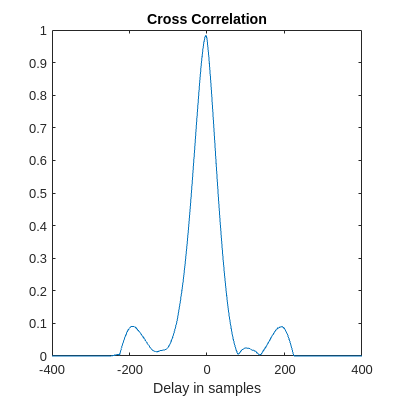

path = "../MATLAB_generated/cpp_sensed_parameters/cross_correlation_result.bin";
result = simulator.read_from_file(path,true,"float32");

path = "../MATLAB_generated/cpp_sensed_parameters/cross_correlation_lags.bin";
lags = simulator.read_from_file(path,false,"int");

%plot the computed cross correlation
clf;
plot(lags,abs(result));
xlabel("Delay in samples")
title("Cross Correlation")